# **Final Project**

### **COURSE: **TIP8522 - ANALYSIS AND CONTROL OF LINEAR SYSTEMS VIA LINEAR MATRIX INEQUALITIES

### PROFESSOR: FABRICIO GONZALEZ NOGUEIRA

### STUDENT: ANDREZA COSTA NASCIMENTO

clear all; close all; clc;

## 1. System Dynamics and Modeling

The purpose to implement a control synthesis to the Magnetic Levitation System is to regulate the electric current in the circuit so the electromagnetic force can be adjusted to be equal to the weight of the steel ball in an equilibrium state. 

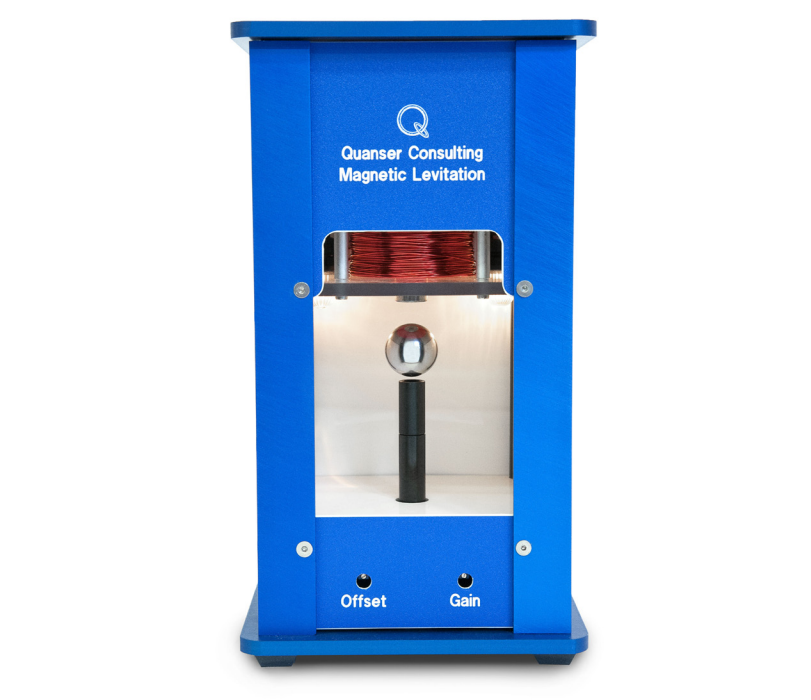

### 1.2.a. Electromagnetic Dynamics Modeling


$$u(t) = V_R +V_L= iR+\frac{dL(x)i}{dt}$$


where, 

u: applied voltage

i: current in the coil of the electromagnet

R: coil's resistance

L: coil's inductance

### 1.2.b. Mechanical Modeling

$F_{ext} = F_{g}- F_{em} = mg-\frac{K_mi(t)^2}{2x^2}=m\ddot{x}$,     if     $\frac{K_m}{2} = K = constant$ then


$$ mg-\frac{Ki(t)^2}{x^2}=m\ddot{x}$$


where,

m: mass of ball

x: position of the ball

g: gravitational constant

Km: magnetic force constant

The parameter values are defined bellow (Quanser 2013):

K = 3.265e-05;          % 1.24e-4 (Barrie,1994), or 7.39e-5 (Wong,1986), or 3.265e-05 (Quanser)
g = 9.81;               % [m/s^2]
R = 11;                 % [Ω]

### 1.3. Nonlinear Model

Assuming that the dynamic of the magnetic levitation can be described by the following differential equations:

(1). $\frac{dx}{dt} = v
$

(2). $Ri+\frac{dL(x)i}{dt} = u$

(3). $m\frac{dv}{dt} = mg - K \left(\frac{i}{x} \right)^2$

L(x) is a nonlinear function of the ball's position x. A typical approximation is to assume this inductance varies inversely with respect to the ball's postition x, that is 

(4). $L(x)=L_1 +\frac{L_0x_0}{x}$

where $L_1$is the inductance constant value as the ball bearing is removed to $x = \infty$. $L_0$ is also a constant and $x_0
$ is the operating levitation gap ($x_0
$ is an arbitraty reference position for the inductance) (Barie, 1996).

Substituting (4) in (2)


$$Ri+\frac{d \left(L_1 +\frac{L_0x_0}{x} \right)i}{dt} = u$$



$$Ri+\frac{d(L_1i)}{dt}+\frac{d \left(\frac{L_0x_0}{x} \right )i}{dt} = u$$



$$Ri+ L_1\frac{di}{dt}+L_0x_0 \left(\frac{\frac{di}{dt}x - i\frac{dx}{dt}}{x^2} \right) = u$$



$$Ri+\left (L_1+\frac{L_0x_0}{x} \right)\frac{di}{dt} - \left(\frac{L_0x_0i}{x^2} \right)\frac{dx}{dt} = u$$


Since x is always kept around the close neighborhood of $x_0$, L can be considered as a constant that will greatly simplify the system model without losing much accuracy. Therefore,


$$L = L_1+\frac{L_0x_0}{x}$$


and


$$Ri+L\frac{di}{dt} - \left(\frac{L_0x_0i}{x^2} \right)\frac{dx}{dt} = u$$


A conservation of energy argument shows that $K = L_0x_0/2$ (Barie, 1994). Defining $x = x_1, v = x_2 $ and $i = x_3$, the state-space form corresponds to 

 
$$\dot{x}_1 = x_2
$$



$$\dot{x}_2 = g - \frac{K}{m} \left (\frac{x_3}{x_1} \right) ^2$$



$$\dot{x}_3=\frac{u}{L}+\frac{2Kx_3x_2}{Lx_1^2}-\frac{Rx_3}{L}$$


### 1.4. Linearization

Assuming that, at the equilibrium point, the velocity is equals to zero, i.e. $x_{02}$ = 0. Therefore, 


$$x_{03} = x_{01}\sqrt{\frac{gm}{K}}$$


The linearized state equations are produced by the deriving the Jacobian formula and substituting the equilibrium vector $x_0=[x_{01} \: x_{02} \: x_{03}]$ in the matrix **A** and **B**. The continuous-time state space representation with disturbance is defined as


$$\dot{x}(t)= Ax(t)+Bu(t)+B_ww(t) \\
z(t)=C_zx(t)+D_{zu}u(t)+D_{zw}w(t) \\
y(t)=Cx(t)+D_{yu}u(t)+D_{yw}w(t)
$$


In the present scenario, the matrix A, B, C and D corresponds to

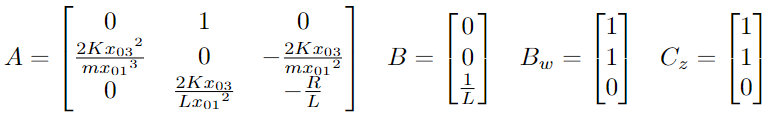

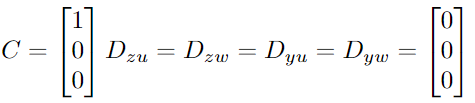

### 1.5. Polytopic Uncertainties

Considering parametric uncertainties in the steel ball mass and the coil inductance such as

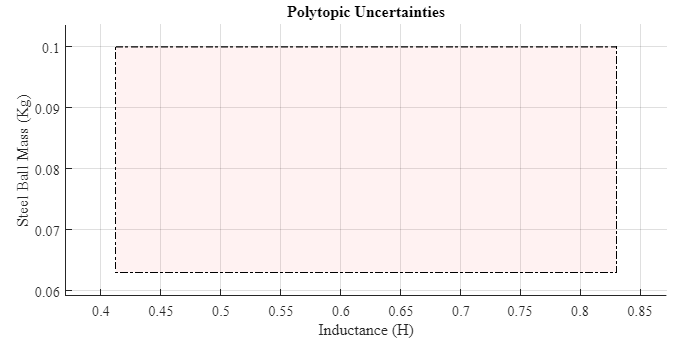

m = [0.063 0.1];       % Data from "Magnectic Levitation Datasheet" (Quanser)
L = [0.4125 0.83];     % Data from "Magnectic Levitation Datasheet" (Quanser)
pgon = polyshape([L(1,1) L(1,1) L(1,2) L(1,2)],[fliplr(m) m]);
plotpol(pgon,'Inductance (H)','Steel Ball Mass (Kg)', 'Polytopic Uncertainties');

Therefore, based on the polytopic uncertainty defined before, the study cases are


$$A_{11},B_{11}:for \: m = 0.016 Kg\: and \: L = 0.4125H\\
A_{12},B_{12}:for \: m = 0.016 Kg\: and \: L = 0.4125H\\
A_{21},B_{21}:for \: m = 0.1 Kg\: and \: L = 0.83H\\
A_{22},B_{22}:for \: m = 0.1 Kg\: and \: L = 0.83H$$


The discrete time state model is obtained by discretizing the model using a sampling time $T_s = 0.001s$

### 1.6. Open Loop Discrete-time and Continuous-time System Response

The system response to a step unit input and its impulse response are plotted bellow for each study case:

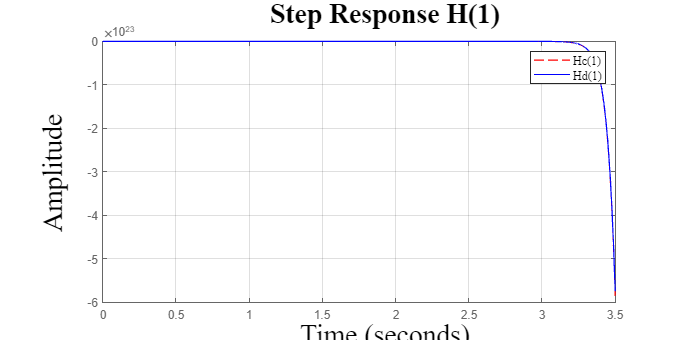

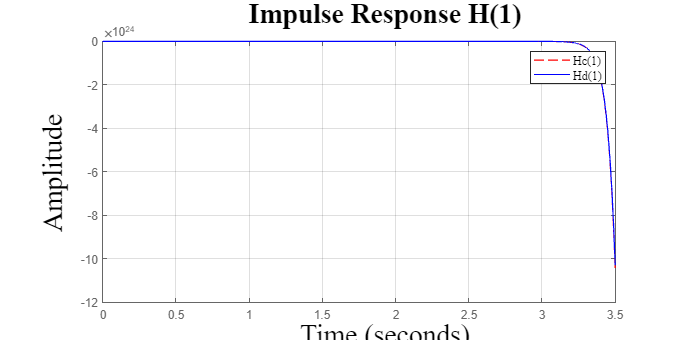

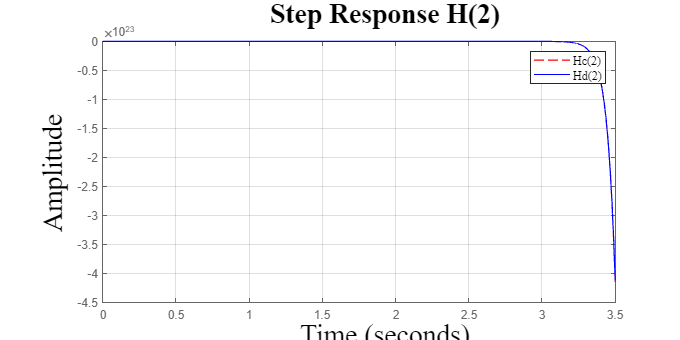

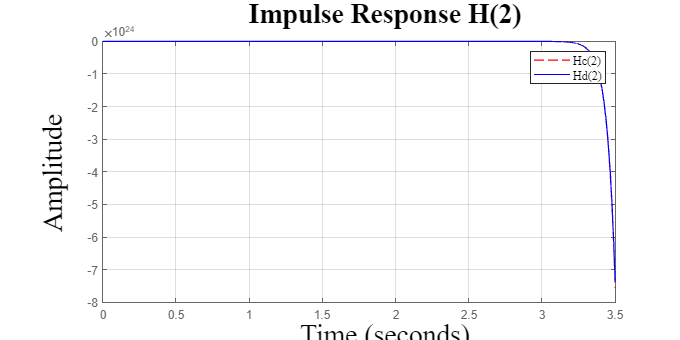

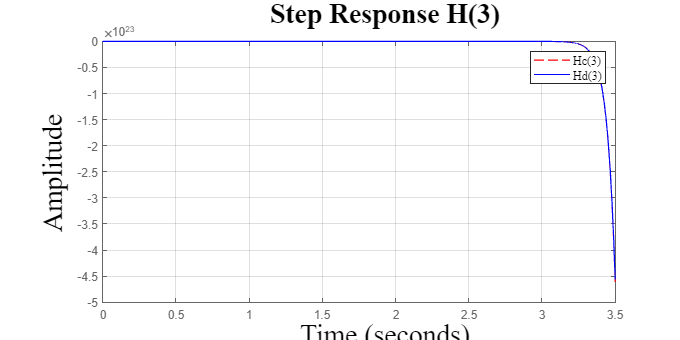

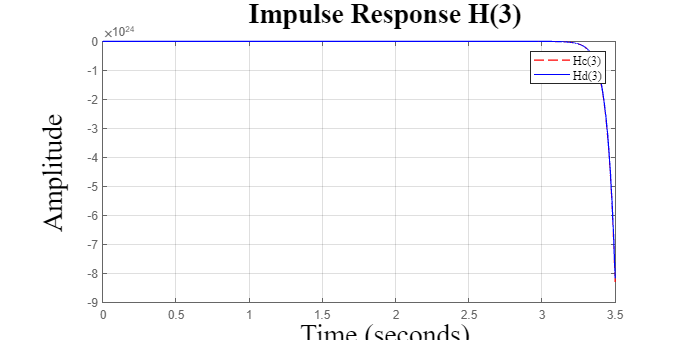

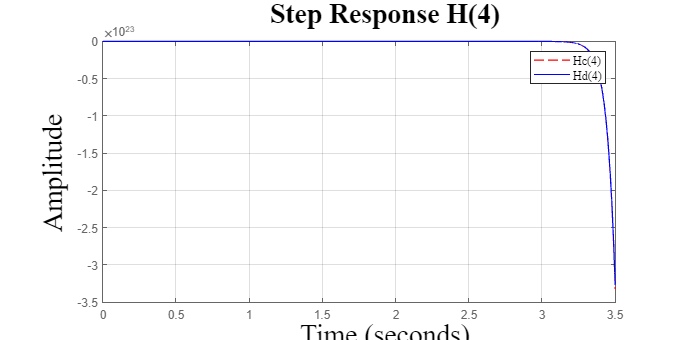

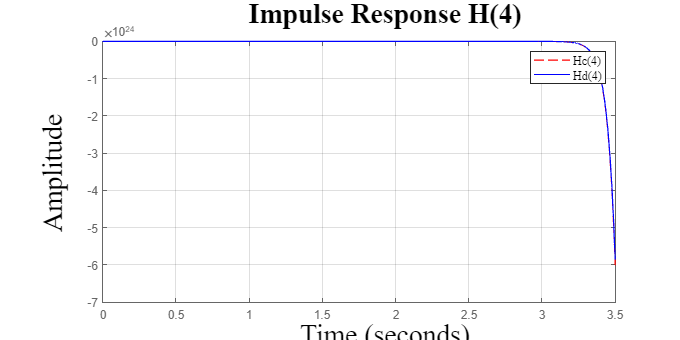

x_01 = 0.06;           % [m] || Data from "Magnectic Levitation Datasheet" (Quanser)
x_02 = 0;              % [m/s]

Bw = [1 1 0]';
Cz = Bw';
C = [1 0 0];
Dyu = zeros(size(C,1),size(Bw,2));
Dzu = Dyu; Dzw = Dzu; Dyw = Dzw;

r = 0;
ts = 0.001;

for i=1:length(m)
    x_03 = x_01*sqrt((g*m(i))/K);
    for j=1:length(L)
        r = r+1;
        A{i,j} = [0 1 0;(2*K*(x_03^2))/(m(i)*(x_01)^3) 0 -(2*K*x_03)/(m(i)*(x_01)^2); 0 (2*K*x_03)/(L(j)*(x_01)^2) -R/L(j)];
        B{i,j} = [0 0 1/L(j)]';
        poles_ol(:,r) = eig(A{i,j});
        Hc(r) = ss(A{i,j},B{i,j},C,Dyu);
        Hd(r) = c2d(Hc(r),ts);
        customizeStepPlot(Hc(r),'--r',Hd(r),'-b', ['Step Response H(',num2str(r),')'], 'Time', 'Amplitude',{['Hc(',num2str(r),')'], ['Hd(',num2str(r),')']});
        customizeImpulsePlot(Hc(r),'--r',Hd(r),'-b', ['Impulse Response H(',num2str(r),')'], 'Time', 'Amplitude',{['Hc(',num2str(r),')'], ['Hd(',num2str(r),')']});
    end
end

## 2. Controller Synthesis

In this section, it is outlined the process of designing a robust state feedback controller, enriched with integral action, and incorporating mixed $H_2/H_\infty$ control technique to handle polytopic uncertainties. The approach incorporates local pole replacement regions to ensure desirable closed-loop system behavior.

### 2.1. Performance Specifications for the Closed-Loop System

The closed-loop system under consideration is a 2nd-order dynamic system. Consequently, defining the desired behavior of this system is pivotal. The performance indexes for this specific plant type enable the calculation of key parameters of the natural frequency and damping ratio. They are used to determine the position of the dominant poles of the 2nd-order closed loop system.

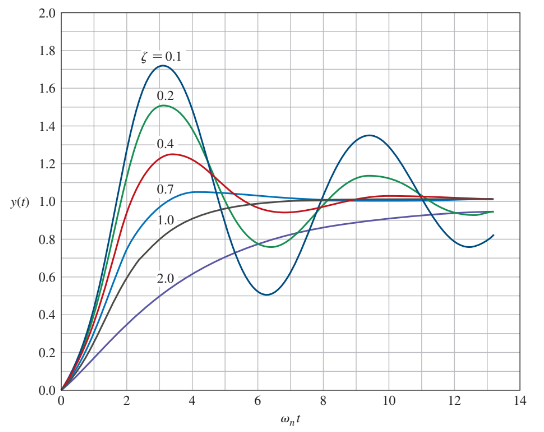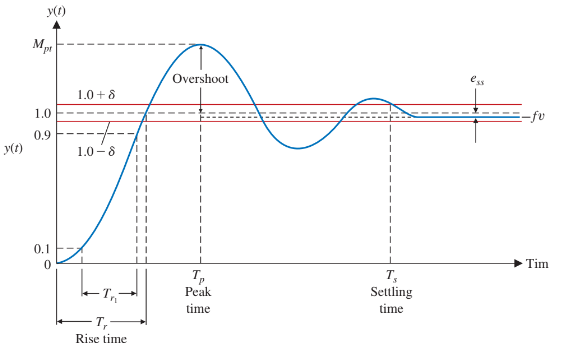

To achieve the desired behavior, it is defined a settling time ($T_s$) of **0.048 seconds** and a percent overshoot ($P.O$) of **1.5%**. The settling time, while considering that the response remains within 2% of the final value, can be expressed as:


$$T_s=\frac{4}{\zeta \omega_n}$$


Here, $\zeta$ represents the damping ratio, and $w_n$ denotes the natural frequency. Alternatively, the percent overshoot can be calculated using:


$$P.O.=100e^{-\zeta \pi/ \sqrt{1- \zeta^2}}$$


By utilizing both of these equations, it becomes possible to calculate the desirable parameters that define the closed-loop system's behavior.

T_set = 0.048;                              % [s]    || Data from "Magnectic Levitation Datasheet" (Quanser)
PO = 1.5;                                   % [%]    || Data from "Magnectic Levitation Datasheet" (Quanser)
final_perc = 2;                             % [%]
[wn,dmp]=omega_dmp(T_set, PO, final_perc);

### 2.2. Delimitation of the D-Stability Region

With the natural frequency and damping ratio defined, the subsequent step involves delineating the D-stability region. This region encompasses the permissible range within which the poles of the closed-loop system should be positioned to ensure stability. By confining the pole locations within this region, a controlled response is achieved that conforms to the specified performance requirements. 

The desirable region was delimited by the intersection of a vertical strip and a conical area, both located on the left side of the real plane. The vertical strip was bounded by the vertical lines $h_1$and $h_2$. As for the conical region, its vertex was positioned at the origin of the complex plane, forming an internal angle of $2 \theta$.

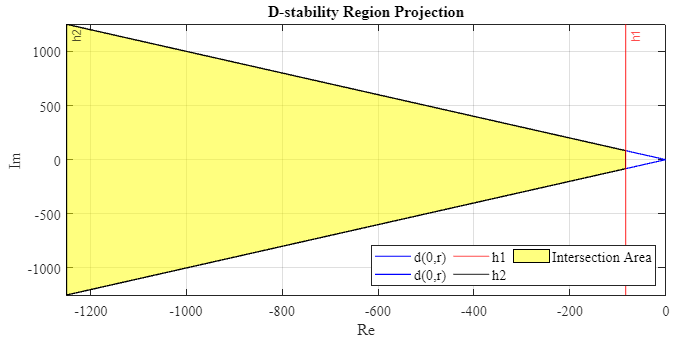

plot_dstability('Re','Im','D-stability Region Projection',{'d(0,r)', 'd(0,r)', 'h1', 'h2', 'Intersection Area'})

The values of $h_1$, $h_2$ and $\theta$ were calculated based on $\zeta$ and $w_n$ using the following equations


$$h_1=-\omega_n \zeta \\
h_2 = ah_1 \\
\theta = arcos(\zeta)$$


where, a is a constant and it was defined as 15.

a = 15;
h1 = -wn*dmp;
h2 = a*h1;
theta = acos(dmp);

The objective is to design a state feedback controller in such a way that the input control signal corresponds to the response of the controller to the state vector acting as its input. To achieve this, the controller is devised as a gain matrix K, and consequently, the control input u(t) can be expressed as $u(t) = Kx(t)$. Hence, building upon the concept of state feedback, the state space equations can be defined as follows:

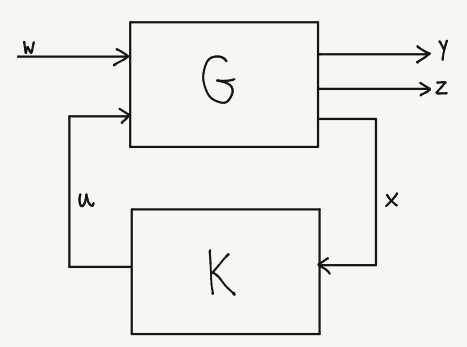


$$\dot{x}(t)= (A+BK)x(t)+B_ww(t) \\
z(t)=(C_z+D_{zu}K)x(t)+D_{zw}w(t) \\
y(t)=(C+D_{yu})x(t)+D_{yw}w(t)$$


The general function are defined for the following LMIs:

- Vertical strip:


$$f_D(z)=z+\bar{z}-2h<0$$


The LMI for the function, taking the state feedback using the K controller into account, is calcutated a new state matrix $A_{cl} = A + BK$. Thus, for $h_1$


$$AQ + QA^T+BY+Y^TB^T-2h_1Q<0 \\
Q\succ 0$$


where, $K=YQ^{-1}$. Alternatevely, for $h_2
$


$$AQ + QA^T+BY+Y^TB^T-2h_2Q>0 \\
Q\succ 0$$


- Conic sector with vertex at origin and internal angle of $2 \theta$:

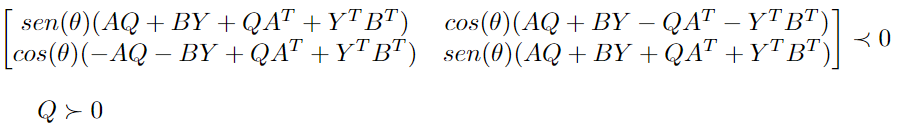

To calculate the gain K of the controller, the following steps are done

[nrA, ncA] = size(A{1,1});
[nrB, ncB] = size(B{1,1});
[nrC, ncC] = size(C);

Q = sdpvar(ncA,nrA);
Y = sdpvar(ncB,nrB);

LMI = [Q>=0];

for i=length(m)
    for j=1:length(L)
        % Right Vertical Strip Constraint
        % Left Vertical Strip Constraint
        % Conic Sector Constraints
        LMI = [LMI, A{i,j}*Q+Q*A{i,j}'+B{i,j}*Y+Y'*B{i,j}'-2*h1*Q<=0];
        LMI = [LMI, A{i,j}*Q+Q*A{i,j}'+B{i,j}*Y+Y'*B{i,j}'-2*h2*Q>=0];
        LMI = [LMI, [sin(theta)*(A{i,j}*Q+B{i,j}*Y+Q*A{i,j}'+Y'*B{i,j}'),cos(theta)*(A{i,j}*Q+B{i,j}*Y-Q*A{i,j}'-Y'*B{i,j}');
            cos(theta)*(-A{i,j}*Q-B{i,j}*Y+Q*A{i,j}'+Y'*B{i,j}'),sin(theta)*(A{i,j}*Q+B{i,j}*Y+Q*A{i,j}'+Y'*B{i,j}')]<=0];
    end
end

OPT = optimize(LMI);

SeDuMi 1.3.5 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 9, order n = 28, dim = 118, blocks = 8
nnz(A) = 210 + 0, nnz(ADA) = 81, nnz(L) = 45
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            3.24E+06 0.000
  1 :   0.00E+00 7.03E+05 0.000 0.2168 0.9000 0.9000   1.00  1  1  2.1E+03
  2 :   0.00E+00 1.54E+05 0.000 0.2197 0.9000 0.9000   1.00  1  1  4.5E+02
  3 :   0.00E+00 4.85E+04 0.000 0.3143 0.9000 0.9000   1.00  1  1  1.4E+02
  4 :   0.00E+00 4.83E+03 0.000 0.0996 0.9900 0.9900   1.00  1  1  1.4E+01
  5 :   0.00E+00 9.27E+02 0.000 0.1918 0.9000 0.9000   1.00  1  1  2.7E+00
  6 :   0.00E+00 1.82E+02 0.000 0.1967 0.9000 0.9000   1.00  1  1  5.4E-01
  7 :   0.00E+00 7.11E+01 0.000 0.3900 0.9000 0.9000   1.00  1  1  2.1E-01
  8 :   0.00E+00 2.28E+01 0.000 0.3202 0.9000 0.9000   1.00  1  1  6.7E-02
  9 :   0.00E+00 6.05E+00 0.000 0.2656 0.9000 0.9000   1.00  1  1  1.8E-02
 10 :   0.00E+0

checkset(LMI)

 
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|          Constraint|   Primal residual|   Dual residual|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality|        8.7785e-12|      2.9529e-12|
|   #2|   Matrix inequality|        6.5325e-10|      6.8905e-15|
|   #3|   Matrix inequality|        4.7184e-09|      3.4474e-15|
|   #4|   Matrix inequality|        1.1817e-09|      6.7431e-15|
|   #5|   Matrix inequality|        8.6894e-10|      2.2083e-14|
|   #6|   Matrix inequality|        1.6735e-08|      1.0831e-15|
|   #7|   Matrix inequality|        7.9475e-10|      1.3646e-14|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals.|
| In practice, many solvers converge to slightly infeasible    |
| solutions, which may cause some residuals to be negative.    |
| It is up to the user to judge the importance and impact of   |
| slightly negative


K_gain = value(Y)*inv(value(Q));

The pole replacement of the closed-system are plotted, the response of the closed-loop system considering both step unit and impulse the disturbance input, and the frequency response are showed bellow 

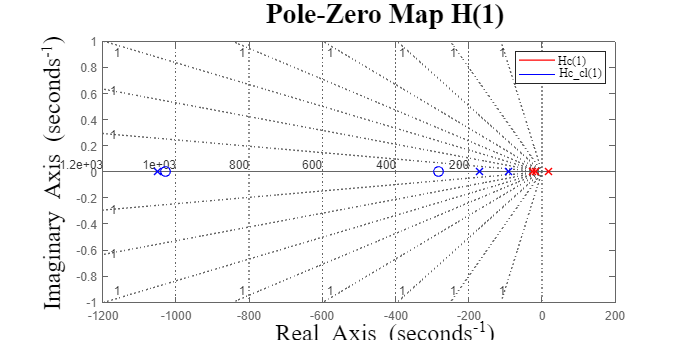

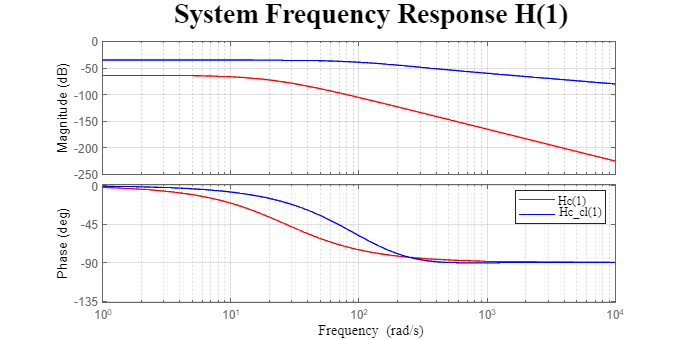

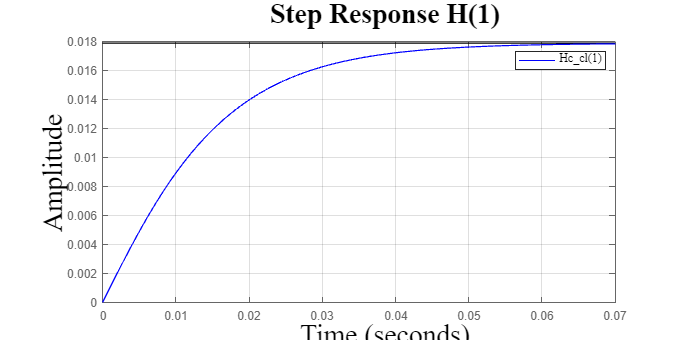

ans = struct with fields:
         RiseTime: 0.0272
    TransientTime: 0.0468
     SettlingTime: 0.0468
      SettlingMin: 0.0161
      SettlingMax: 0.0179
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0179
         PeakTime: 0.0800


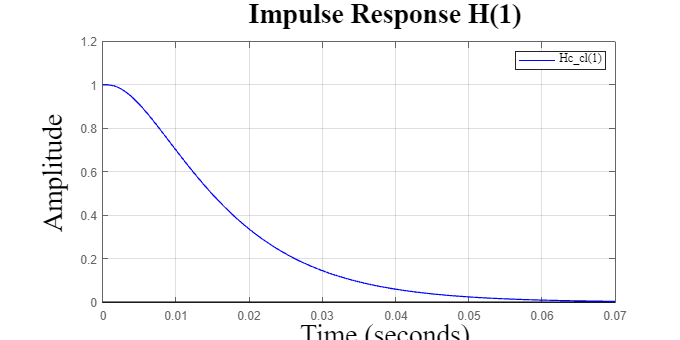

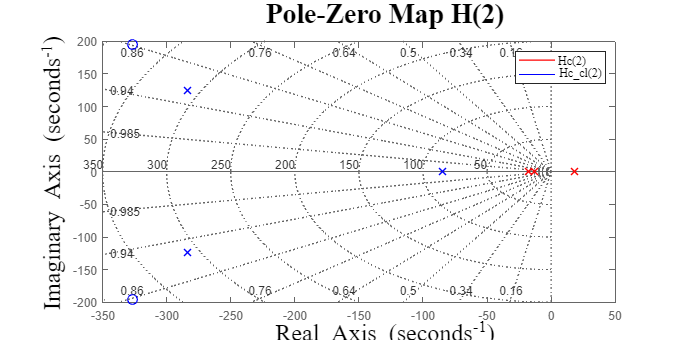

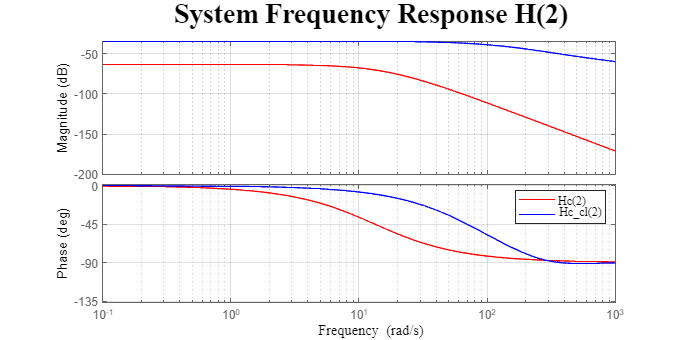

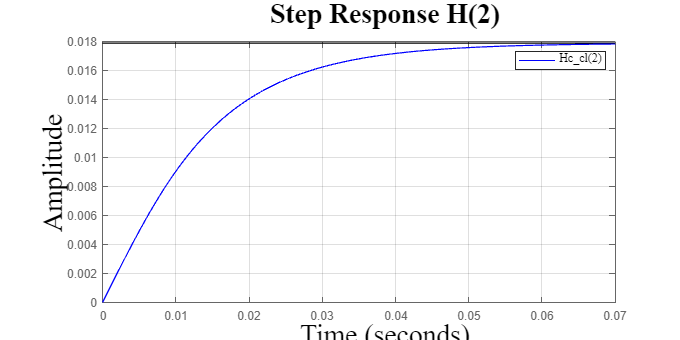

ans = struct with fields:
         RiseTime: 0.0273
    TransientTime: 0.0481
     SettlingTime: 0.0481
      SettlingMin: 0.0161
      SettlingMax: 0.0178
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0178
         PeakTime: 0.0776


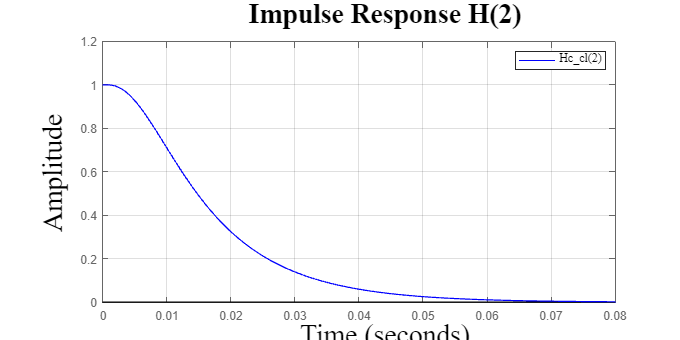

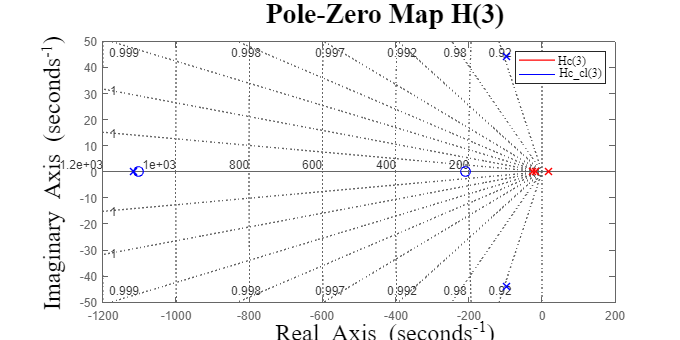

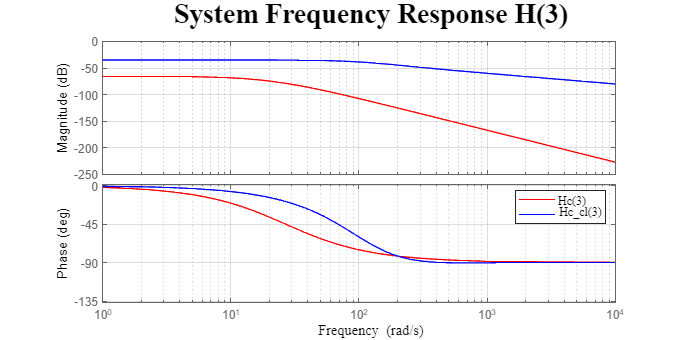

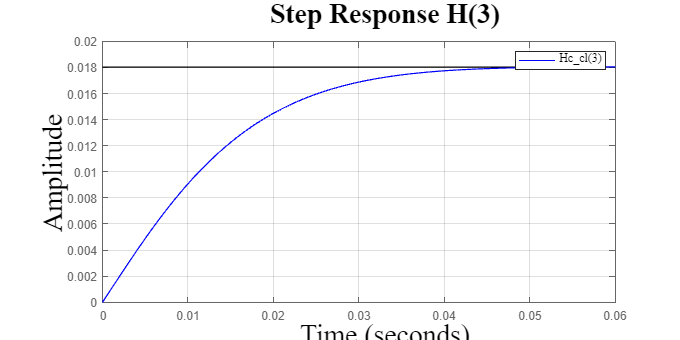

ans = struct with fields:
         RiseTime: 0.0244
    TransientTime: 0.0383
     SettlingTime: 0.0383
      SettlingMin: 0.0163
      SettlingMax: 0.0180
        Overshoot: 0.1218
       Undershoot: 0
             Peak: 0.0180
         PeakTime: 0.0630


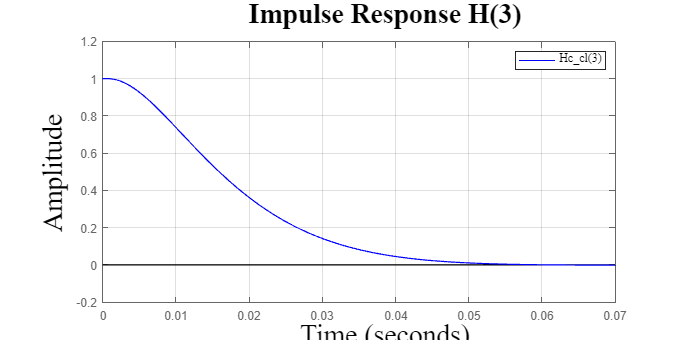

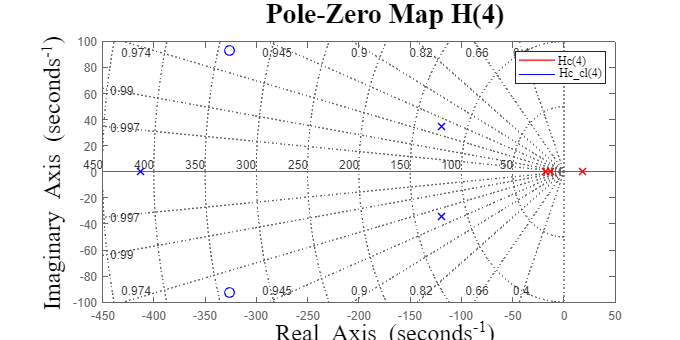

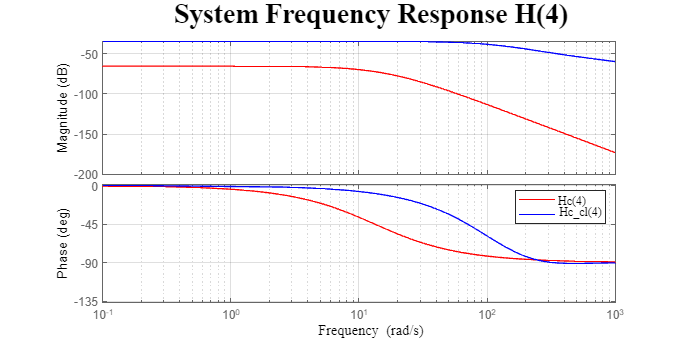

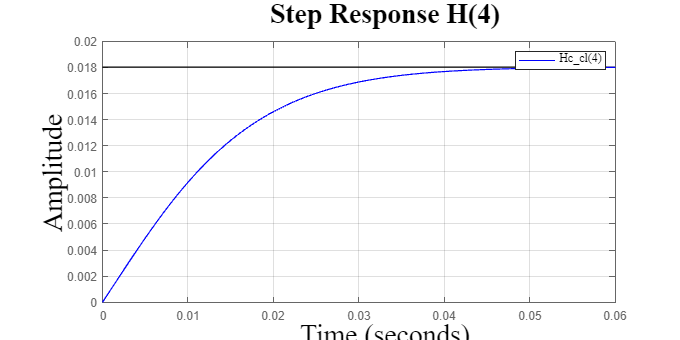

ans = struct with fields:
         RiseTime: 0.0241
    TransientTime: 0.0394
     SettlingTime: 0.0394
      SettlingMin: 0.0163
      SettlingMax: 0.0180
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0180
         PeakTime: 0.0651


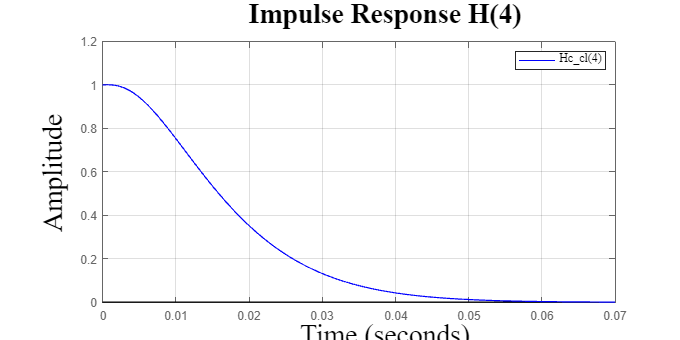

C_cl = C+Dyu*K_gain;
D_cl = Dyw;

r = 0;

B_cl = [];

for i=1:length(m)
    for j=1:length(L)
        r = r+1;
        A_cl{i,j} = A{i,j}+B{i,j}*K_gain;
        B_cl{i,j} = Bw;
        poles_cl(:,r) = eig(A_cl{i,j});
        Hc_cl(r) = ss(A_cl{i,j},B_cl{i,j},C_cl,D_cl);
        customPzplot(Hc(r),Hc_cl(r), ['Pole-Zero Map H(',num2str(r),')'], {['Hc(',num2str(r),')'], ['Hc_cl(',num2str(r),')']});
        customBode(Hc(r),Hc_cl(r), ['System Frequency Response H(',num2str(r),')'], {['Hc(',num2str(r),')'], ['Hc_cl(',num2str(r),')']});
        customizeStepPlot(Hc_cl(r),'-b', ['Step Response H(',num2str(r),')'], 'Time', 'Amplitude',{['Hc_cl(',num2str(r),')']});
        stepinfo(Hc_cl(r))
        customizeImpulsePlot(Hc_cl(r),'-b', ['Impulse Response H(',num2str(r),')'], 'Time', 'Amplitude',{['Hc_cl(',num2str(r),')']});
    end
end

Observing the pole-zero map plot, it becomes evident that the poles of the closed-loop system are within the d-stability area defined by the project specifications. Furthermore, the performance specifications designed for the 2nd-order system have also been met. This is confirmed when verifying this information using the MATLAB function `stepinfo()`. However, none of the earlier steps guarantee that the system's response fulfills reference tracking. This issue becomes apparent when analyzing the step response plot of each implemented system.

### 2.3. Adding Integral Action

To address this problem, an integral action is incorporated into the system. Mathematically, this necessitates augmenting the state space equations with an additional state representing the integral of the error. This introduces an extra equation stating that the derivative of the integral of position ($x_1=x$) is equal to position. The input, $r$, is now introduced into the system before the integrator. 

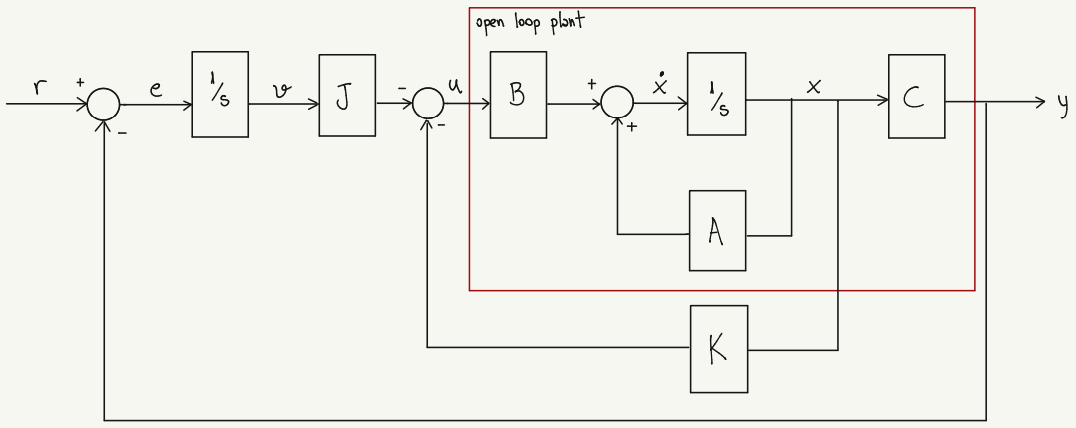

Consider the simplified form of the state space equation of a system as


$$\dot{x}=Ax(t)+Bu(t) \\
y = Cx(t)+ Du(t)$$


where$D = 0$. Defining the error $v$ as the new state, which represents the integral of the error, and $e$ the derivative of this state, therefore,


$$e=r-y$$


where $y = Cx(t)$. Then,


$$e=r-Cx(t)$$


Note that as $\dot{v}$ is the derivative of the integral of the error, $e$ is simply the error itself. This equation will be placed at the bottom of the matrices. The reference $r$, therefore, now appears as an additional input to the system. The system's output remains unchanged.

Bw_au = [1 1 0 0]';
Cz_au = Bw_au';
C_au = [1 0 0 0];
Dyu_au = zeros(size(C_au,1),size(Bw_au,2));
Dzu_au = Dyu_au; Dzw_au = Dzu_au; Dyw_au = Dzw_au;

r = 0;

for i=1:length(m)
    x_03 = x_01*sqrt((g*m(i))/K);
    for j=1:length(L)
        r = r+1;
        A_au{i,j} = [A{i,j} zeros(nrA,1); -C zeros(nrC,1)];
        B_au{i,j} = [B{i,j}' 0]';
        paug_ol(:,r) = eig(A_au{i,j});
        Hc_au(r) = ss(A_au{i,j},B_au{i,j},C_au,Dyu_au);
    end
end

Br = [zeros(ncB,nrB) 1]';

[nrA_au, ncA_au] = size(A_au{1,1});
[nrB_au, ncB_au] = size(B_au{1,1});
[nrBw_au, ncBw_au] = size(Bw_au);
[nrDzu_au, ncDzu_au] = size(Dzu_au);

Q = sdpvar(ncA_au,nrA_au);
Y = sdpvar(ncB_au,nrB_au);

LMI = [Q>=0];

for i=length(m)
    for j=1:length(L)
        % Right Vertical Strip Constraint
        % Left Vertical Strip Constraint
        % Conic Sector Constraints
        LMI = [LMI, A_au{i,j}*Q+Q*A_au{i,j}'+B_au{i,j}*Y+Y'*B_au{i,j}'-2*h1*Q<=0];
        LMI = [LMI, A_au{i,j}*Q+Q*A_au{i,j}'+B_au{i,j}*Y+Y'*B_au{i,j}'-2*h2*Q>=0];
        LMI = [LMI, [sin(theta)*(A_au{i,j}*Q+B_au{i,j}*Y+Q*A_au{i,j}'+Y'*B_au{i,j}'),cos(theta)*(A_au{i,j}*Q+B_au{i,j}*Y-Q*A_au{i,j}'-Y'*B_au{i,j}');
            cos(theta)*(-A_au{i,j}*Q-B_au{i,j}*Y+Q*A_au{i,j}'+Y'*B_au{i,j}'),sin(theta)*(A_au{i,j}*Q+B_au{i,j}*Y+Q*A_au{i,j}'+Y'*B_au{i,j}')]<=0];
    end
end

OPT = optimize(LMI);

SeDuMi 1.3.5 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 14, order n = 37, dim = 209, blocks = 8
nnz(A) = 342 + 0, nnz(ADA) = 196, nnz(L) = 105
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.45E+06 0.000
  1 :   0.00E+00 5.32E+05 0.000 0.2168 0.9000 0.9000   1.00  1  1  2.1E+03
  2 :   0.00E+00 1.17E+05 0.000 0.2197 0.9000 0.9000   1.00  1  1  4.5E+02
  3 :   0.00E+00 3.67E+04 0.000 0.3143 0.9000 0.9000   1.00  1  1  1.4E+02
  4 :   0.00E+00 3.66E+03 0.000 0.0996 0.9900 0.9900   1.00  1  1  1.4E+01
  5 :   0.00E+00 7.02E+02 0.000 0.1919 0.9000 0.9000   1.00  1  1  2.7E+00
  6 :   0.00E+00 1.38E+02 0.000 0.1969 0.9000 0.9000   1.00  1  1  5.4E-01
  7 :   0.00E+00 5.39E+01 0.000 0.3900 0.9000 0.9000   1.00  1  1  2.1E-01
  8 :   0.00E+00 1.73E+01 0.000 0.3202 0.9000 0.9000   1.00  1  1  6.7E-02
  9 :   0.00E+00 4.58E+00 0.000 0.2656 0.9000 0.9000   1.00  1  1  1.8E-02
 10 :   0.00

checkset(LMI)

 
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|          Constraint|   Primal residual|   Dual residual|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality|        3.5439e-16|      7.7854e-12|
|   #2|   Matrix inequality|       -1.4763e-14|      1.9293e-14|
|   #3|   Matrix inequality|        3.0312e-13|       7.882e-15|
|   #4|   Matrix inequality|         2.308e-14|      1.8948e-14|
|   #5|   Matrix inequality|       -2.0719e-14|      6.2811e-14|
|   #6|   Matrix inequality|        8.0492e-13|      2.9543e-15|
|   #7|   Matrix inequality|        1.5534e-14|      3.8018e-14|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals.|
| In practice, many solvers converge to slightly infeasible    |
| solutions, which may cause some residuals to be negative.    |
| It is up to the user to judge the importance and impact of   |
| slightly negative


K_au = value(Y)*inv(value(Q));

Ccl_au = C_au+Dyu_au*K_au;
Dcl_au = Dyw_au;

In the case where $B_{cl} = B_r$ (matrix associated with the reference input signal $r$): 

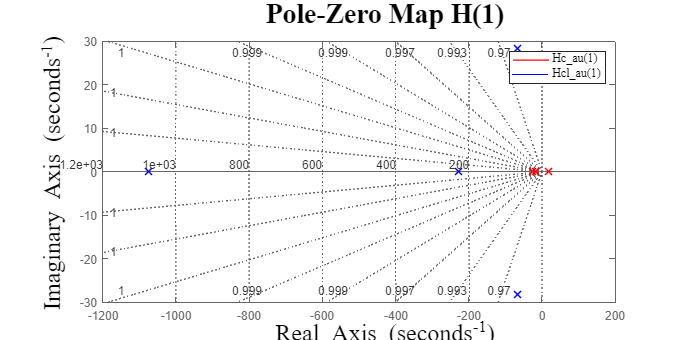

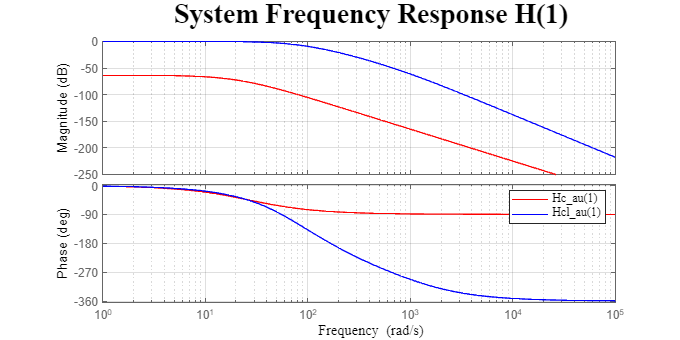

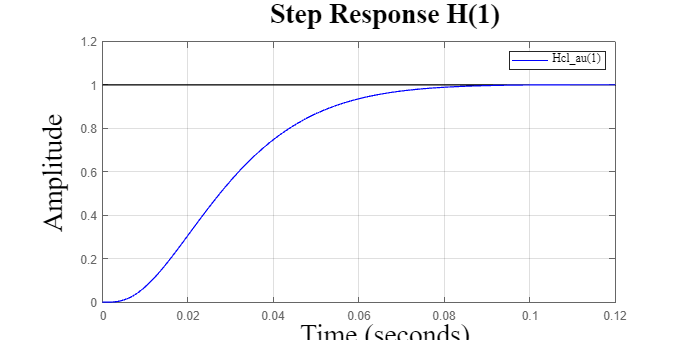

ans = struct with fields:
         RiseTime: 0.0425
    TransientTime: 0.0739
     SettlingTime: 0.0739
      SettlingMin: 0.9048
      SettlingMax: 1.0005
        Overshoot: 0.0515
       Undershoot: 0
             Peak: 1.0005
         PeakTime: 0.1182


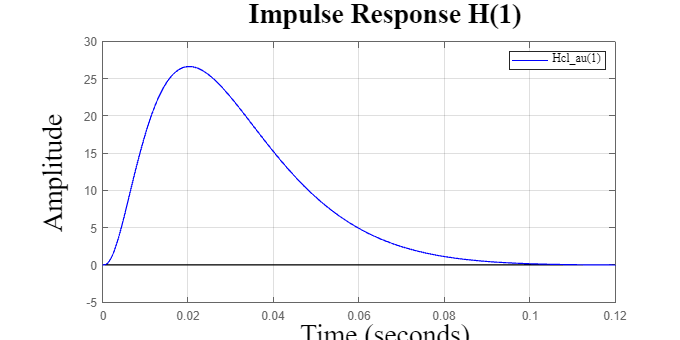

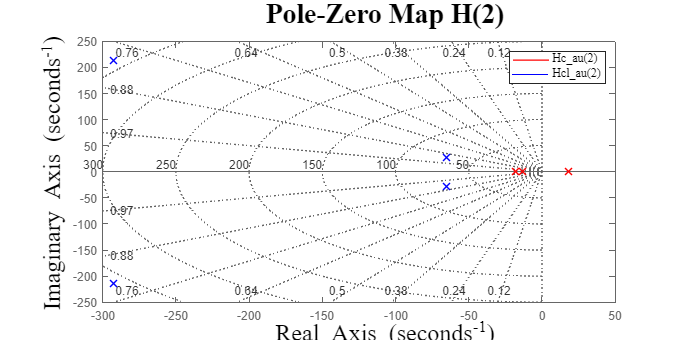

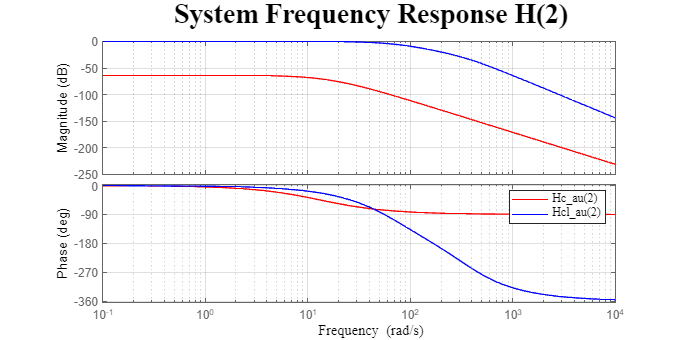

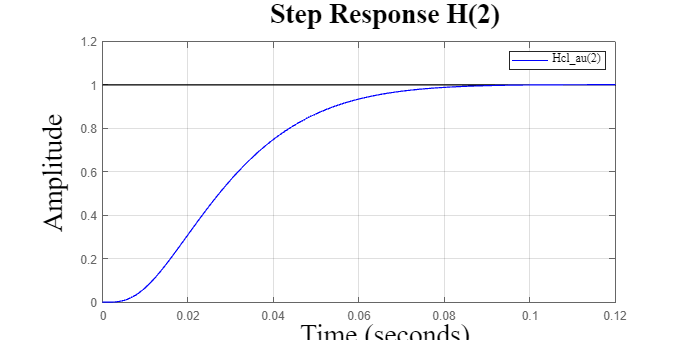

ans = struct with fields:
         RiseTime: 0.0425
    TransientTime: 0.0743
     SettlingTime: 0.0743
      SettlingMin: 0.9032
      SettlingMax: 1.0006
        Overshoot: 0.0624
       Undershoot: 0
             Peak: 1.0006
         PeakTime: 0.1185


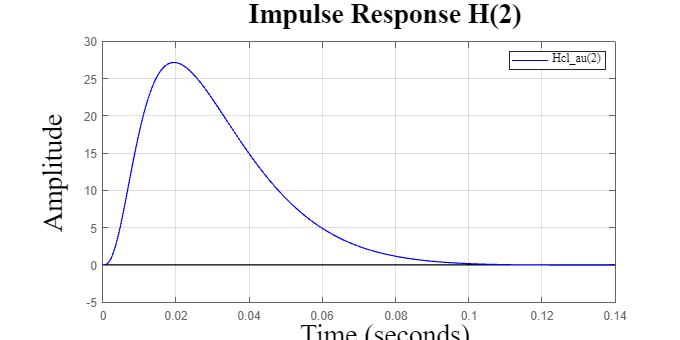

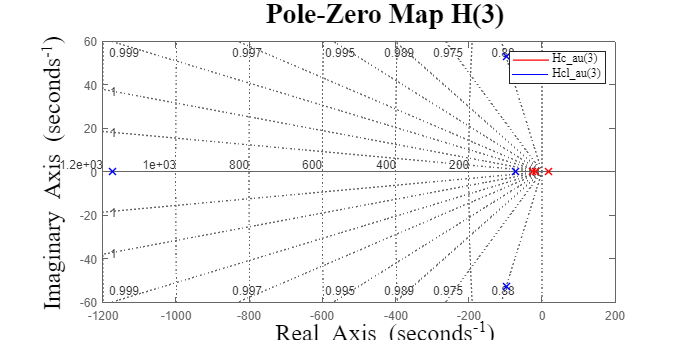

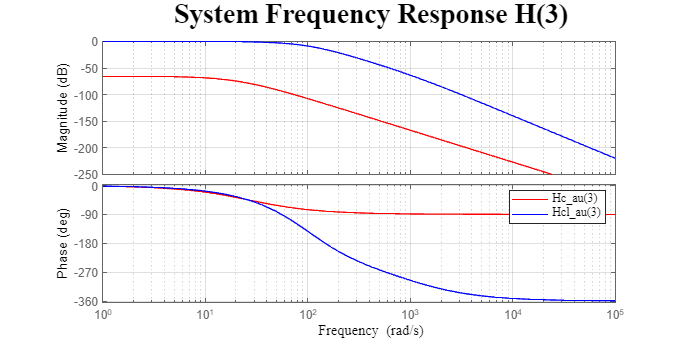

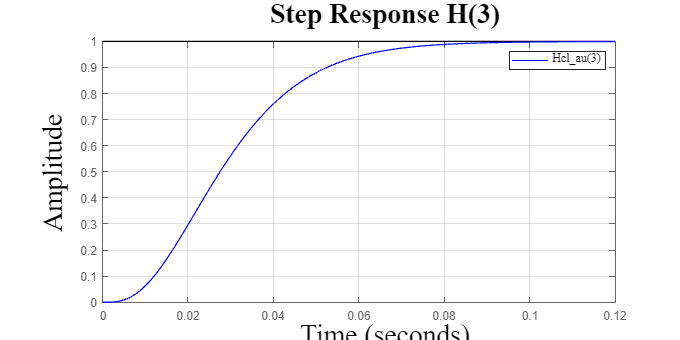

ans = struct with fields:
         RiseTime: 0.0404
    TransientTime: 0.0733
     SettlingTime: 0.0733
      SettlingMin: 0.9031
      SettlingMax: 0.9994
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9994
         PeakTime: 0.1191


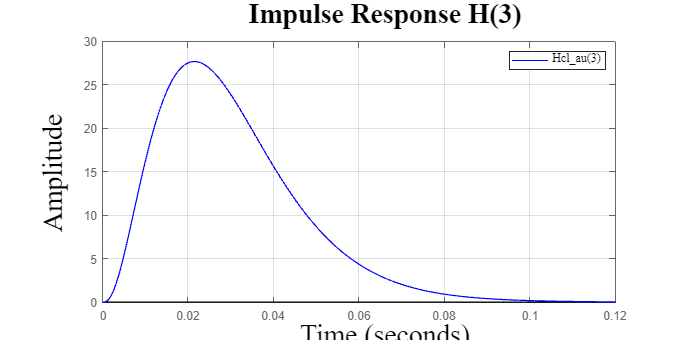

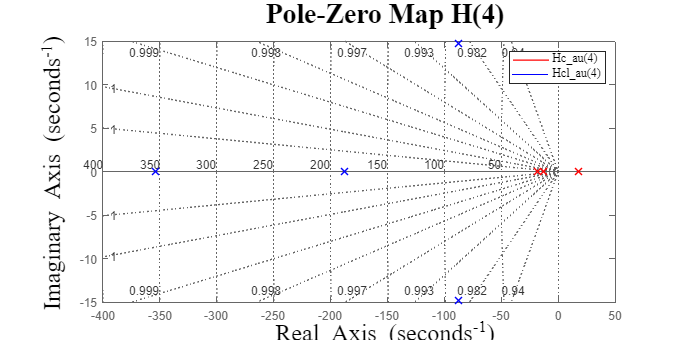

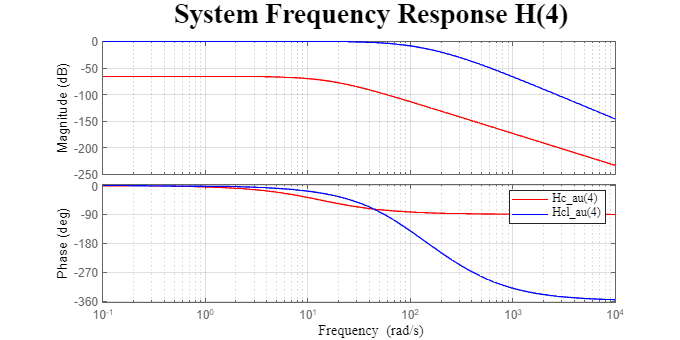

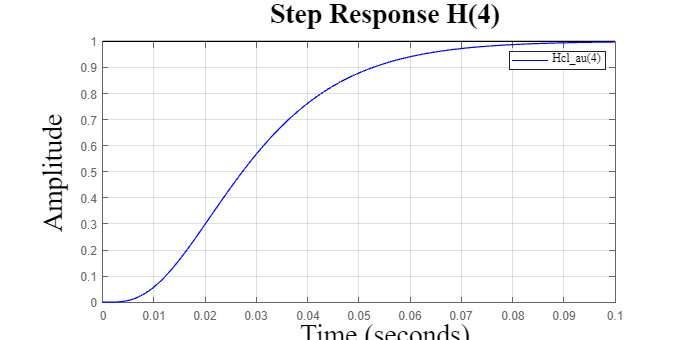

ans = struct with fields:
         RiseTime: 0.0405
    TransientTime: 0.0740
     SettlingTime: 0.0740
      SettlingMin: 0.9017
      SettlingMax: 0.9992
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9992
         PeakTime: 0.1123


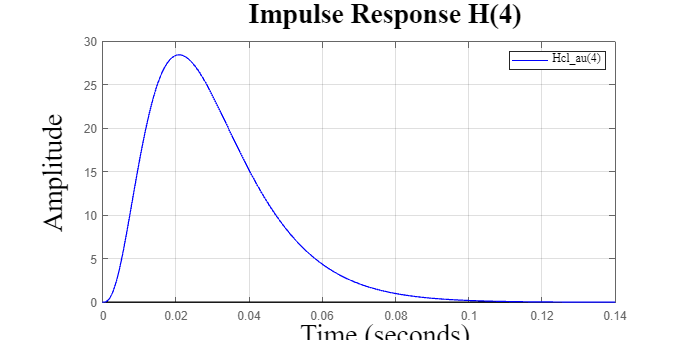

r = 0;

Bcl_au = [];

for i=1:length(m)
    for j=1:length(L)
        r = r+1;
        Acl_au{i,j} = A_au{i,j}+B_au{i,j}*K_au;
        Bcl_au{i,j} = Br;
        % Bcl_au{i,j} = Bw_au;
        paug_cl(:,r) = eig(Acl_au{i,j});
        Hcl_au(r) = ss(Acl_au{i,j},Bcl_au{i,j},Ccl_au,Dcl_au);
        customPzplot(Hc_au(r),Hcl_au(r), ['Pole-Zero Map H(',num2str(r),')'], {['Hc_au(',num2str(r),')'], ['Hcl_au(',num2str(r),')']});
        customBode(Hc_au(r),Hcl_au(r), ['System Frequency Response H(',num2str(r),')'], {['Hc_au(',num2str(r),')'], ['Hcl_au(',num2str(r),')']});
        customizeStepPlot(Hcl_au(r),'-b', ['Step Response H(',num2str(r),')'], 'Time', 'Amplitude',{['Hcl_au(',num2str(r),')']});
        stepinfo(Hcl_au(r))
        customizeImpulsePlot(Hcl_au(r),'-b', ['Impulse Response H(',num2str(r),')'], 'Time', 'Amplitude',{['Hcl_au(',num2str(r),')']});
    end
end

Alternatively, in the case where $B_{cl} = B_w$ (matrix associated with the reference disturbance signal $w$):

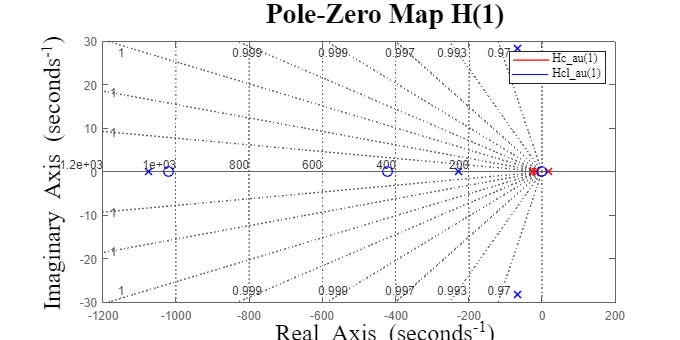

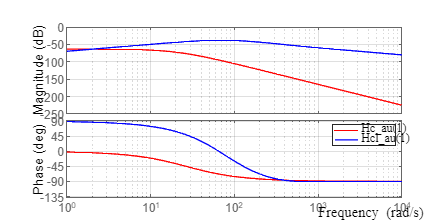

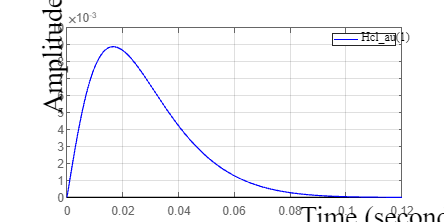

ans = struct with fields:
         RiseTime: 0
    TransientTime: 0.0848
     SettlingTime: NaN
      SettlingMin: -4.8655e-06
      SettlingMax: 0.0088
        Overshoot: Inf
       Undershoot: Inf
             Peak: 0.0088
         PeakTime: 0.0164


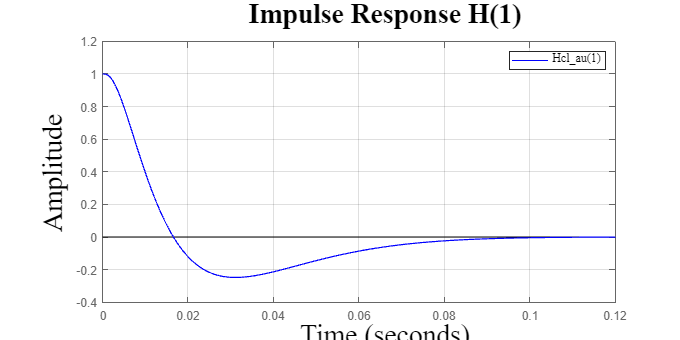

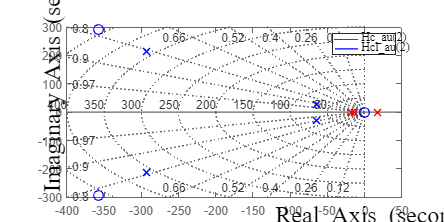

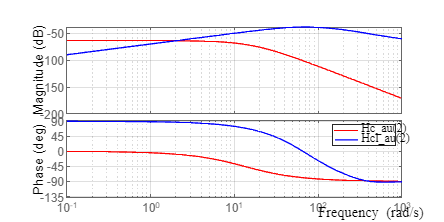

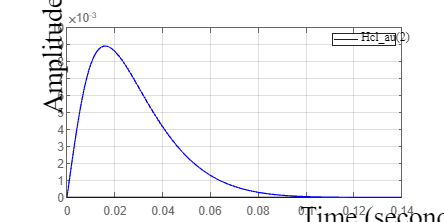

ans = struct with fields:
         RiseTime: 0
    TransientTime: 0.0856
     SettlingTime: NaN
      SettlingMin: -5.5871e-06
      SettlingMax: 0.0089
        Overshoot: Inf
       Undershoot: Inf
             Peak: 0.0089
         PeakTime: 0.0163


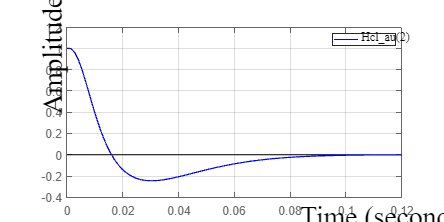

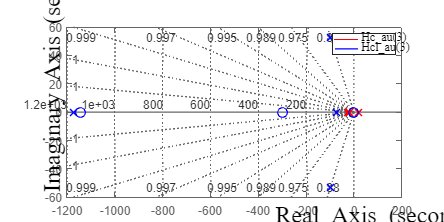

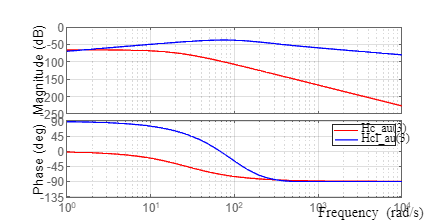

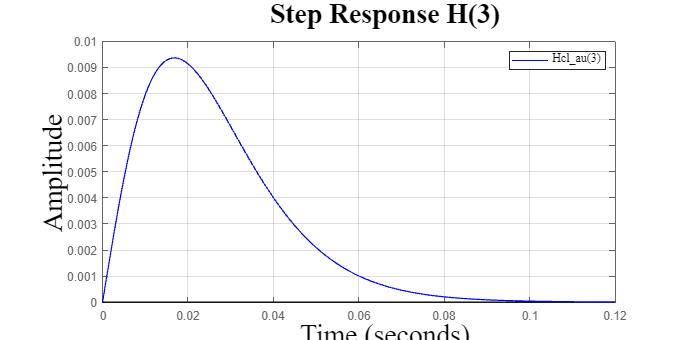

ans = struct with fields:
         RiseTime: 0
    TransientTime: 0.0811
     SettlingTime: NaN
      SettlingMin: 0
      SettlingMax: 0.0094
        Overshoot: Inf
       Undershoot: 0
             Peak: 0.0094
         PeakTime: 0.0170


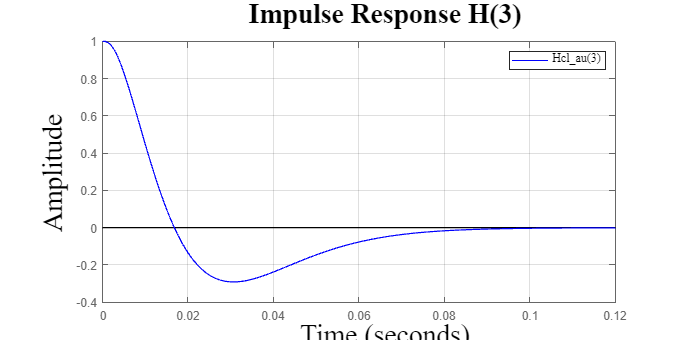

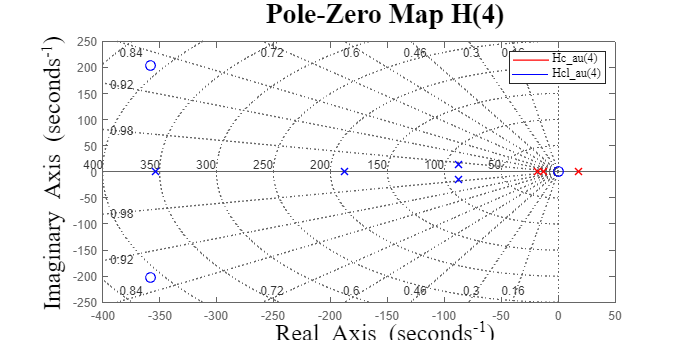

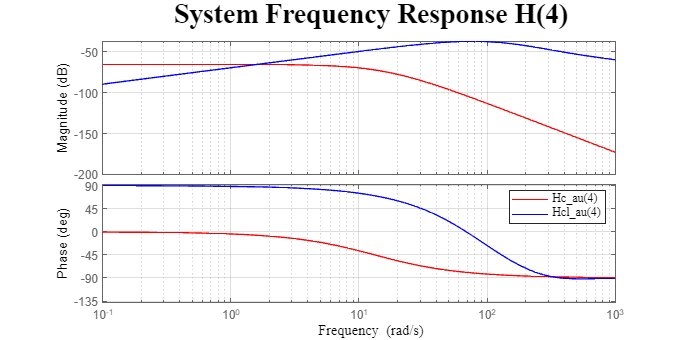

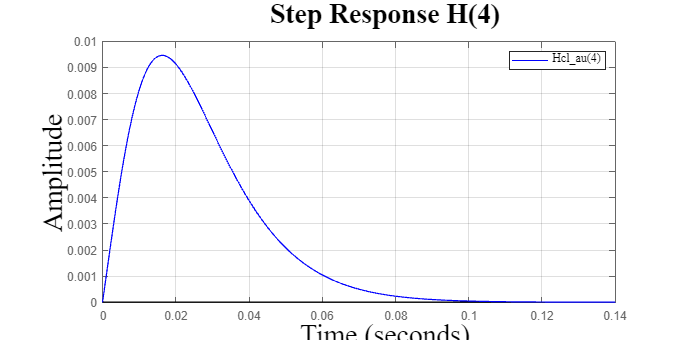

ans = struct with fields:
         RiseTime: 0
    TransientTime: 0.0825
     SettlingTime: NaN
      SettlingMin: 0
      SettlingMax: 0.0095
        Overshoot: Inf
       Undershoot: 0
             Peak: 0.0095
         PeakTime: 0.0162


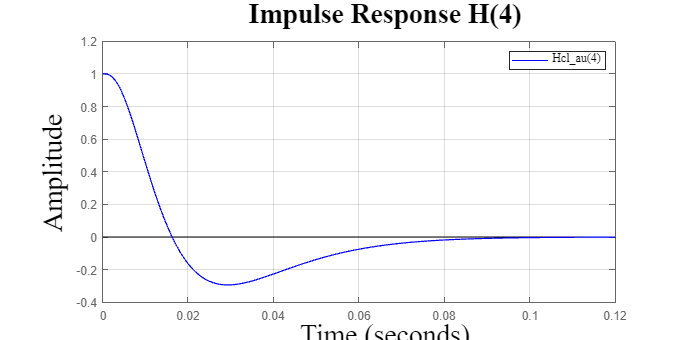

r = 0;

Bcl_au = [];

for i=1:length(m)
    for j=1:length(L)
        r = r+1;
        Acl_au{i,j} = A_au{i,j}+B_au{i,j}*K_au;
        % Bcl_au{i,j} = Br;
        Bcl_au{i,j} = Bw_au;
        paug_cl(:,r) = eig(Acl_au{i,j});
        Hcl_au(r) = ss(Acl_au{i,j},Bcl_au{i,j},Ccl_au,Dcl_au);
        customPzplot(Hc_au(r),Hcl_au(r), ['Pole-Zero Map H(',num2str(r),')'], {['Hc_au(',num2str(r),')'], ['Hcl_au(',num2str(r),')']});
        customBode(Hc_au(r),Hcl_au(r), ['System Frequency Response H(',num2str(r),')'], {['Hc_au(',num2str(r),')'], ['Hcl_au(',num2str(r),')']});
        customizeStepPlot(Hcl_au(r),'-b', ['Step Response H(',num2str(r),')'], 'Time', 'Amplitude',{['Hcl_au(',num2str(r),')']});
        stepinfo(Hcl_au(r))
        customizeImpulsePlot(Hcl_au(r),'-b', ['Impulse Response H(',num2str(r),')'], 'Time', 'Amplitude',{['Hcl_au(',num2str(r),')']});
    end
end

### 2.3. Mixed $H_2/H_{\infty}$ Control

Mixed $H_2/H_{\infty}$ control is a significant strategy employed to mitigate the adverse impact of disturbances on critical signals within a control system. It involves designing a controller that adheres to both $H_2$ and $H_{\infty}$ norm conditions, aiming to attenuate disturbances effectively. These norms provide quantifiable metrics for the magnitudes of the signals involved and the system operators that influence them. By incorporating $H_2$ and $H_{\infty}$ control criteria, this approach offers a comprehensive solution to enhance the resilience of the control system against various disturbances (Abreu, Lopes and Mike, 2010).

In the realm of robust control theory, a convergence of time-domain specifications, exemplified by $H_2$ control, and frequency-domain specifications, represented by $H_\infty}$ control, holds immense value. The integration of $H_2$ and $H_{\infty}$ control objectives into a single controller marks a significant advancement in achieving robustness. The objective of this methodology revolves around crafting a state feedback controller that not only guarantees a predetermined level of disturbance attenuation as indicated by the $H_\infty}$ norm but also optimizes the system's performance through the minimization of the $H_2$ performance index. By marrying these two distinct control paradigms, mixed $H_2/H_{\infty}$ control provides a holistic framework that enhances system robustness while considering both transient and frequency-based requirements (Abreu, Lopes and Mike, 2010).

Consider a close-loop system defined as

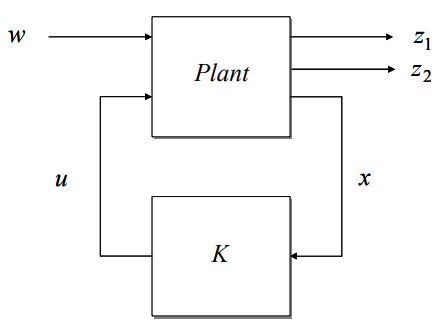


$$\dot{x}(t)= (A+BK)x(t)+B_ww(t) \\
z_1(t)=(C_{z_1}+D_{z_1u}K)x(t)+D_{z_1w}w(t) \\
z_2(t)=(C_{z_2}+D_{z_2u}K)x(t)+D_{z_2w}w(t)$$


Let $T_{z_1w}$ and $T_{z_2w}$ as the closed-loop transfer function from $w$ to $z_1$and $z_2$, respectively, the multiobjective $H_2/H_{\infty}$ control strategy is described as it follows. Find a static state feedback law ($u(t) = Kx(t)$) such that ${\left \| T_{z_2w} \right \|}_{2}$ is minimized over all state feedback gains $K$ such that what also minimizes the $\left \| T_{z_1w} \right \|_{\infty}$.

### 2.3.1. $H_2$ Control Strategy

The $H_2$ norm of the transfer function $T_{z_2w}$ is finite if and only if, $D_{z_2w} = 0$. In this case, the $H_2$ norm of $T_{z_2w}$ is given by


$${\left \| T_{z_2w} \right \|}_{2}^{2} = tr \left[ \left(C_{z_2}+D_{z_2u}K \right)X_2\left(C_{z_2}+D_{z_2u}K \right)^T \right]$$


where the symmetric positive definite matrix $X_2$ is obtained by solving the following inequality (Boyd et al, 1994):


$$\left (A+BK \right)X_2 + X_2\left (A+BK \right)^T+B_wB_w^T<0$$


by rearrangement of inequality above, using the Shur complement, and defining $Z_2=KX_2$, the following inequality can be obtained, for $X_2 \succ 0$:

The objective $H_2$ control can be given by minimizing the constraint ${\left \| T_{z_2w} \right \|}_{2}^{2} = tr \left[ \left(C_{z_2}+D_{z_2u}K \right)X_2\left(C_{z_2}+D_{z_2u}K \right)^T \right]$


$$\underset{K}{min}\:tr \left (SR^{-1}S^T \right)$$


or, introducing a new matrix variable $M$, i.e., the LMI,

In this way, the $H_2$norm of $T_{z_2w}$ is the minimum of $tr(M)$ or formally:

$\underset{M,X_2,Z_2}{min}\: tr \left(M \right)$ subject to

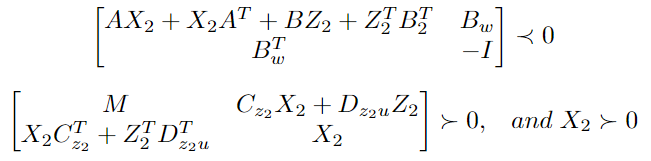

### 2.3.2. $H_{\infty}$ Control Strategy

For time invariant systems, the $H_{\infty}$ norm of the transfer function $w$ to $z_1$ is minimized when the effect of the disturbance on $z_1$ is diminished or that the infinity norm of the $T_{z_1w}$ be less than $\gamma $, i.e,


$$\left \| T_{z_1w} \right \|_{\infty} = \underset{w}{sup} \frac{\left \| z_1 \right \|_{2}}{\left \| w \right \|_{2}}\leq  \gamma$$


where $\gamma$, which is a positive real number, serves as the measure of performance.

The bounded real lemma plays a central role in obtaining the $H_{\infty}$ constraint. There exists a quadratic Lyapunov function $V(x) = x^TPx$ such that for all time $t$,


$$\frac{d}{dt}V(x)+z_1^Tz_1-\gamma ^2 w^Tw<0
 $$


where $P$ is a symmetric positive definite matrix.

Substituting $z_1(t)=(C_{z_1}+D_{z_1u}K)x(t)+D_{z_1w}w(t)$ into the inequality above, and assuming $D_{z_1w}$, the following inquality can be obtained


$$\left[ \left(A+BK \right)x+B_ww \right]^TPx+x^TP\left[ \left(A+BK \right)x+B_ww \right]+ \left(C_{z_1}+D_{z_1u}K \right )^Tx^T\left(C_{z_1}+D_{z_1u}K \right )x - \gamma^2w^Tw<0$$


By rearrangement of the inequality yields

Using the Schur complement for the inequality


$$\left(A+BK \right)^TP+P\left(A+BK \right)+ \left(C_{z_1}+D_{z_1u}K \right )^T\left(C_{z_1}+D_{z_1u}K \right )-PB_w\gamma^{-2}B_w^TP<0$$


Multiplying the equation above by $P^{-1}$ from right and left, the following inequality can be obtained


$$P^{-1}\left(A+BK \right)^T+\left(A+BK \right)P^{-1}+ P^{-1}\left(C_{z_1}+D_{z_1u}K \right )^T\left(C_{z_1}+D_{z_1u}K \right )P^{-1}-B_w\gamma^{-2}B_w^T<0$$


By putting equation in LMI form again

Multiplying by

from right and left, and letting $X_{\infty}=\gamma P^{-1}$, yields

Using the Shur complement again and Letting $Z_{\infty}=KX_{\infty}$, the following convex problem is obtained:

$\underset{X_{\infty},Z_{\infty}}{min}\: \gamma$ subject to

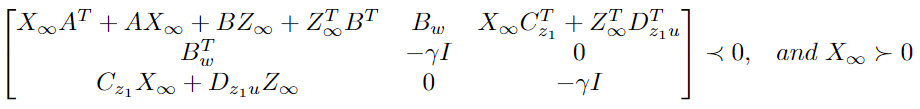

### 2.3. The Mixed $H_2/H_{\infty}$ Control Strategy

The mixed $H_2/H_{\infty}$ control problem is to minimize the $H_2$ norm of $T_{z_2w}$ over all state feedback gains $K$ such that what also minimizes the $H_{\infty}$ norm constraint. Therefore, the inequalities presented on the end of the previous sections are combined letting $X = X_2=X_{\infty}$ (unique solution of $K$), and $Z=KX$.

In this way, the multiobjective $H_2/H_{\infty}$ control using $H_2$ and $H_{\infty}$ performance constraints can be given by 

$\underset{M,X,Z}{min}\: tr \left(M \right)$ subject to

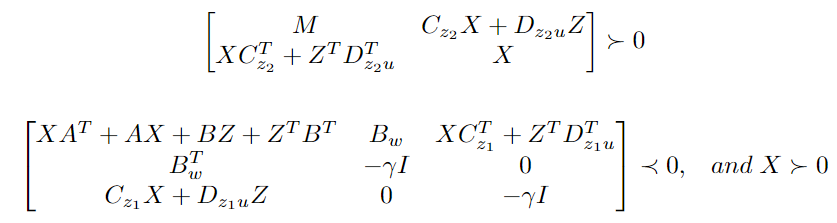

After finding a solution ($M$, $X$ and $Z$) to this multiobjective control problem, the optimal feedback control law is obtained as


$$K = ZX^{-1}$$
 

X = sdpvar(ncA_au,nrA_au);      % Q = P = X
Z = sdpvar(ncB_au,nrB_au);      % Y = Z
M = sdpvar(ncBw_au,ncBw_au);    % J = M

gamma = 2.622;                % gamma_min
% gamma = 3;
% gamma = 3.369;                % gamma_max

LMI = [];

LMI = [X>=0];
LMI = [LMI, M>=0];

for i=length(m)
    for j=1:length(L)

        % Right Vertical Strip Constraint
        % Left Vertical Strip Constraint
        % Conic Sector Constraints
        LMI = [LMI, [A_au{i,j}*X+X*A_au{i,j}'+B_au{i,j}*Z+Z'*B_au{i,j}'-2*h1*X]<=0];
        LMI = [LMI, [A_au{i,j}*X+X*A_au{i,j}'+B_au{i,j}*Z+Z'*B_au{i,j}'-2*h2*X]>=0];
        LMI = [LMI, [sin(theta)*(A_au{i,j}*X+B_au{i,j}*Z+X*A_au{i,j}'+Z'*B_au{i,j}'),cos(theta)*(A_au{i,j}*X+B_au{i,j}*Z-X*A_au{i,j}'-Z'*B_au{i,j}');
            cos(theta)*(-A_au{i,j}*X-B_au{i,j}*Z+X*A_au{i,j}'+Z'*B_au{i,j}'),sin(theta)*(A_au{i,j}*X+B_au{i,j}*Z+X*A_au{i,j}'+Z'*B_au{i,j}')]<=0];
        
        % H-inf Constraint (Abreu, Lopes and Mike, 2010)
        LMI = [LMI, [X*A_au{i,j}'+A_au{i,j}*X+B_au{i,j}*Z+Z'*B_au{i,j}',Bw_au,X*Cz_au'+Z'*Dzu_au';
            Bw_au',-gamma*eye(ncBw_au,ncBw_au),zeros(ncBw_au,ncBw_au);
            Cz_au*X+Dzu_au*Z,zeros(ncDzu_au,nrDzu_au),-gamma*eye(nrDzu_au,nrDzu_au)]<=0];
    end
end

% H2 Constraints (Abreu, Lopes and Mike, 2010)
LMI = [LMI, [M,Cz_au*X+Dzu_au*Z;
    X*Cz_au'+Z'*Dzu_au',X]>=0];

OPT = optimize(LMI,trace(M));

SeDuMi 1.3.5 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 15, order n = 55, dim = 307, blocks = 11
nnz(A) = 434 + 0, nnz(ADA) = 217, nnz(L) = 116
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.37E+05 0.000
  1 :  -1.31E+00 6.18E+04 0.000 0.2607 0.9000 0.9000   1.29  1  1  2.4E+03
  2 :  -4.81E+00 1.50E+04 0.000 0.2421 0.9000 0.9000   0.12  1  1  1.8E+03
  3 :  -1.54E+01 4.89E+03 0.000 0.3272 0.9000 0.9000  -0.74  1  1  1.8E+03
  4 :  -7.43E+01 1.04E+03 0.000 0.2128 0.9000 0.9000  -0.95  1  1  1.9E+03
  5 :  -8.37E+02 9.14E+01 0.000 0.0878 0.9900 0.9900  -0.98  1  1  1.8E+03
  6 :  -3.20E+03 2.13E+01 0.000 0.2332 0.9000 0.9000  -0.96  1  1  1.7E+03
  7 :  -9.30E+03 6.28E+00 0.000 0.2945 0.9000 0.9000  -0.88  1  1  1.5E+03
  8 :  -2.29E+04 2.02E+00 0.000 0.3219 0.9000 0.9000  -0.80  1  1  1.3E+03
  9 :  -7.04E+04 4.64E-01 0.000 0.2297 0.9000 0.9000  -0.74  1  1  1.0E+03
 10 :  -6.6

checkset(LMI)

 
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|    ID|               Constraint|   Primal residual|   Dual residual|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|    #1|        Matrix inequality|        1.0615e-17|      1.7047e-08|
|    #2|   Elementwise inequality|        8.7308e-05|      1.0996e-07|
|    #3|        Matrix inequality|       -6.0189e-16|      1.5643e-11|
|    #4|        Matrix inequality|        1.7766e-15|      1.1807e-11|
|    #5|        Matrix inequality|       -3.3035e-16|      2.1953e-11|
|    #6|        Matrix inequality|           -0.6174|      1.3321e-11|
|    #7|        Matrix inequality|       -6.3492e-16|      4.0787e-11|
|    #8|        Matrix inequality|        2.3952e-14|       9.293e-12|
|    #9|        Matrix inequality|       -4.8389e-16|      4.3269e-11|
|   #10|        Matrix inequality|           -0.6174|      2.6863e-11|
|   #11|        Matrix inequality|        1.0615e-17|      1.7046e-08|
++++

ans = struct with fields:
         RiseTime: 0
    TransientTime: 0.0691
     SettlingTime: NaN
      SettlingMin: 0
      SettlingMax: 0.0068
        Overshoot: Inf
       Undershoot: 0
             Peak: 0.0068
         PeakTime: 0.0127


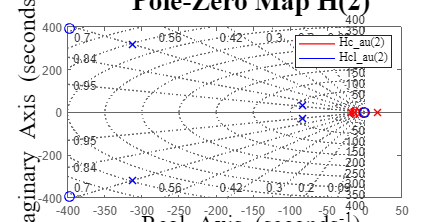

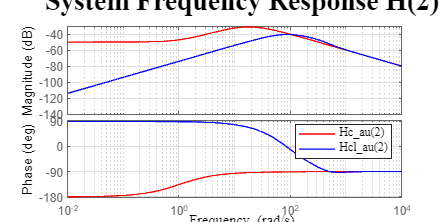

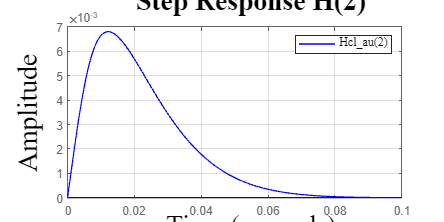

ans = struct with fields:
         RiseTime: 0
    TransientTime: 0.0697
     SettlingTime: NaN
      SettlingMin: -1.1518e-06
      SettlingMax: 0.0068
        Overshoot: Inf
       Undershoot: Inf
             Peak: 0.0068
         PeakTime: 0.0121


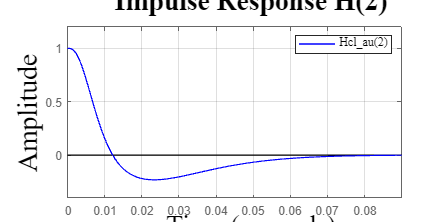

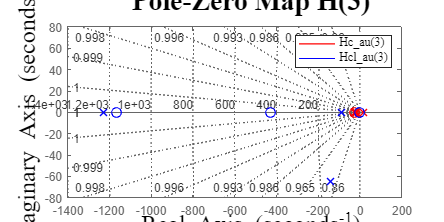

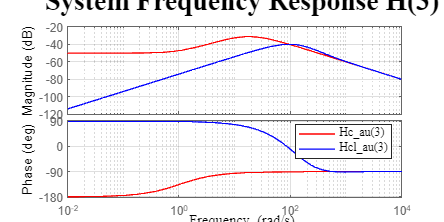

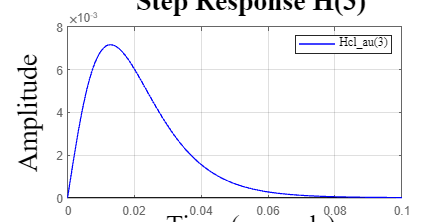

ans = struct with fields:
         RiseTime: 0
    TransientTime: 0.0672
     SettlingTime: NaN
      SettlingMin: 0
      SettlingMax: 0.0072
        Overshoot: Inf
       Undershoot: 0
             Peak: 0.0072
         PeakTime: 0.0128


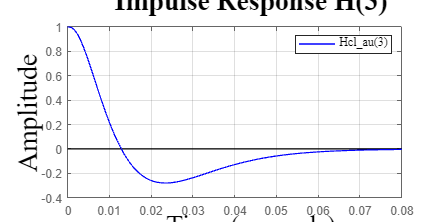

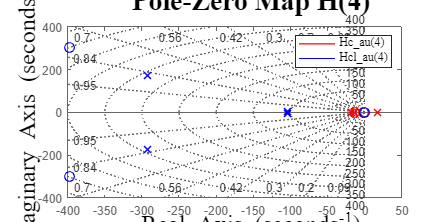

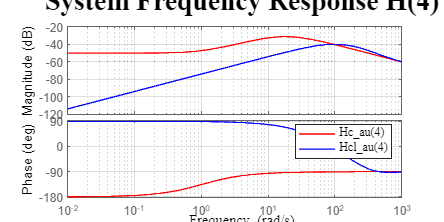

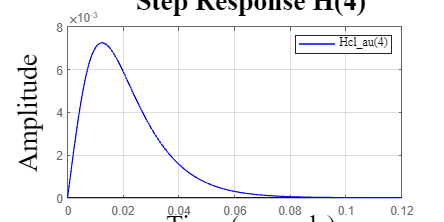

ans = struct with fields:
         RiseTime: 0
    TransientTime: 0.0680
     SettlingTime: NaN
      SettlingMin: 0
      SettlingMax: 0.0073
        Overshoot: Inf
       Undershoot: 0
             Peak: 0.0073
         PeakTime: 0.0124


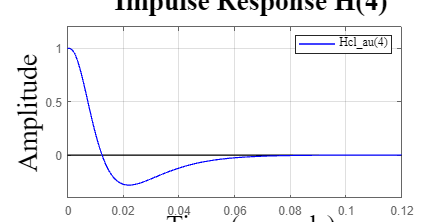


K_law = value(Z)*inv(value(X));
trM = trace(value(M));

Ccl_au = C_au+Dyu_au*K_law;
Dcl_au = Dyw_au;

r = 0;

Bcl_au = [];

for i=1:length(m)
    for j=1:length(L)
        r = r+1;
        Acl_au{i,j} = A_au{i,j}+B_au{i,j}*K_law;
        % Bcl_au{i,j} = Br;
        B_au{i,j} = Bw_au;
        Bcl_au{i,j} = Bw_au;
        paug_cl(:,r) = eig(Acl_au{i,j});
        Hc_au(r) = ss(A_au{i,j},B_au{i,j},C_au,Dyu_au);
        Hcl_au(r) = ss(Acl_au{i,j},Bcl_au{i,j},Ccl_au,Dcl_au);
        customPzplot(Hc_au(r),Hcl_au(r), ['Pole-Zero Map H(',num2str(r),')'], {['Hc_au(',num2str(r),')'], ['Hcl_au(',num2str(r),')']});
        customBode(Hc_au(r),Hcl_au(r), ['System Frequency Response H(',num2str(r),')'], {['Hc_au(',num2str(r),')'], ['Hcl_au(',num2str(r),')']});
        customizeStepPlot(Hcl_au(r),'-b', ['Step Response H(',num2str(r),')'], 'Time', 'Amplitude',{['Hcl_au(',num2str(r),')']});
        stepinfo(Hcl_au(r))
        customizeImpulsePlot(Hcl_au(r),'-b', ['Impulse Response H(',num2str(r),')'], 'Time', 'Amplitude',{['Hcl_au(',num2str(r),')']});
    end
end